## Análisis del transistor BFP450

bfp450_polarizado = sparameters('BFP450_w_noise_VCE_1.0V_IC_0.11A.s2p');
subplot(2,1,1)
rfplot(bfp450_polarizado)
title('Transistor BFP450, I_c=0.11A, V_{CE}=1V')
subplot(2,1,2)
rfplot(bfp450_polarizado,'angle')

## Sistema diseñado

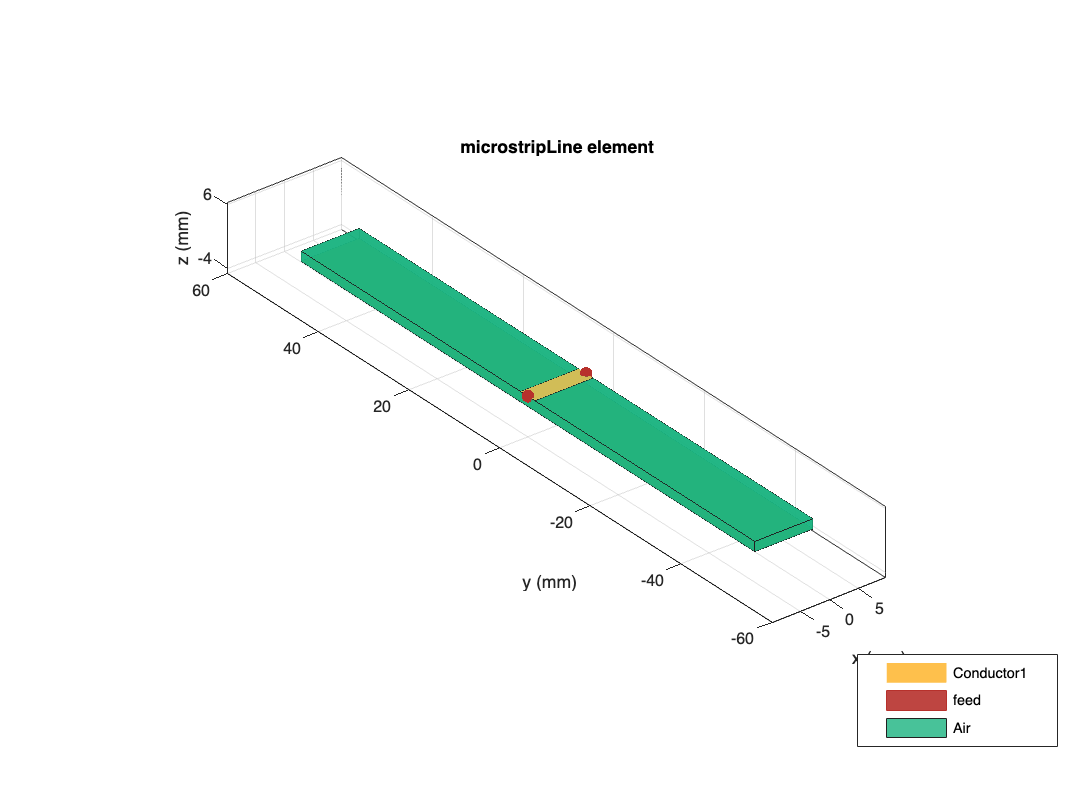

d = dielectric('EpsilonR',4.15);
microstrip_in1 = txlineMicrostrip( ...
    "EpsilonR", 4.15, ...
    "Width", 3.19e-3, ...
    "Thickness", 0, ...
    "LineLength", 10e-3, ...
    "StubMode", "NotAStub",...
    "Termination", "NotApplicable"...
    );
tx1 = microstripLine(microstrip_in1);
tx1.GroundPlaneWidth = 100e-3;
tx1.Substrate = d;
tx1.Height = 1.6e-3;
show(tx1)

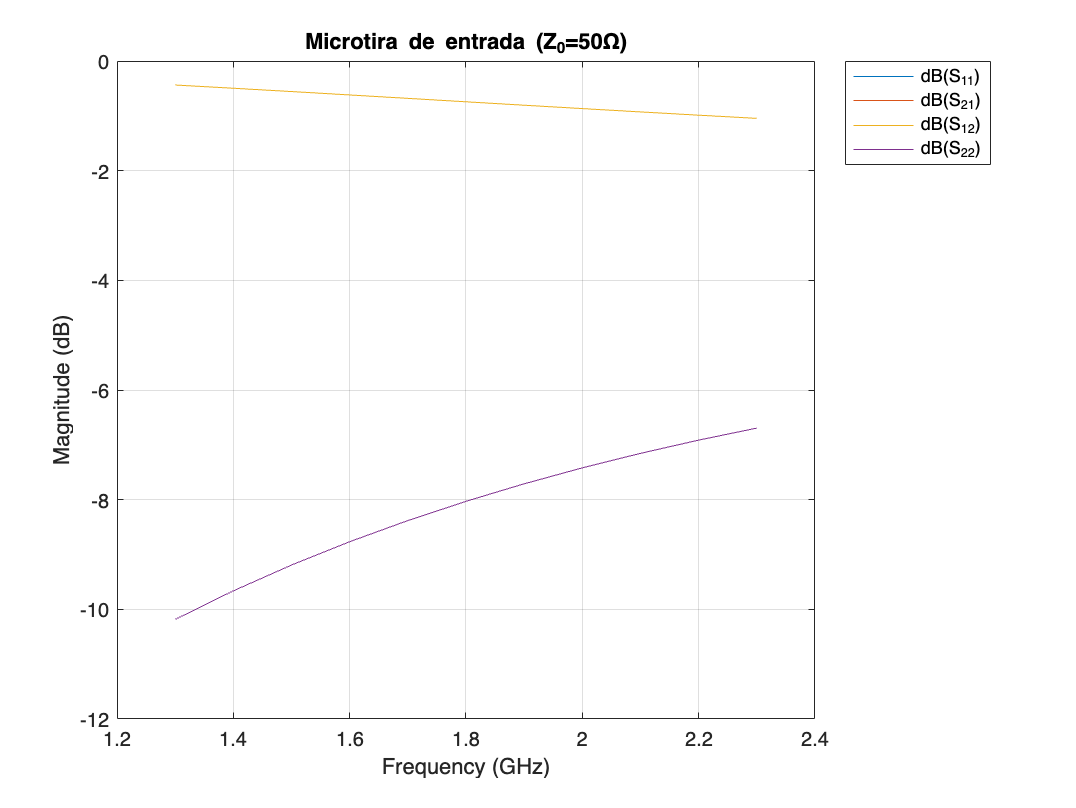

microstrip_in2 = txlineMicrostrip( ...
    "EpsilonR", 4.15, ...
    "Width", 3.19e-3, ...
    "Thickness", 35e-6, ...
    "LineLength", 10e-3, ...
    "StubMode", "NotAStub",...
    "Termination", "NotApplicable"...
    );
tx2 = microstripLine(microstrip_in2);
lamb4_in = txlineMicrostrip( ...
    "EpsilonR", 4.15, ...
    "Width", 7.37e-3, ...
    "Thickness", 35e-6, ...
    "LineLength", 22.5e-3, ...
    "StubMode", "NotAStub",...
    "Termination", "NotApplicable"...
    );
cap_in = txlineMicrostrip( ...
    "EpsilonR", 4.15, ...
    "Width", 3.19e-3, ...
    "Thickness", 35e-6, ...
    "LineLength", 19.4e-3, ...
    "StubMode", "Shunt",...
    "Termination", "Open"...
    );
bfp = sparameters('BFP450_w_noise_VCE_1.0V_IC_0.11A.s2p');
lamb4_out = txlineMicrostrip( ...
    "EpsilonR", 4.15, ...
    "Width", 5.99e-3, ...
    "Thickness", 35e-6, ...
    "LineLength", 22.79e-3, ...
    "StubMode", "NotAStub",...
    "Termination", "NotApplicable"...
    );
cap_out = txlineMicrostrip( ...
    "EpsilonR", 4.15, ...
    "Width", 3.19e-3, ...
    "Thickness", 35e-6, ...
    "LineLength", 4.99e-3, ...
    "StubMode", "Shunt",...
    "Termination", "Open"...
    );
microstrip_out1 = txlineMicrostrip( ...
    "EpsilonR", 4.15, ...
    "Width", 3.19e-3, ...
    "Thickness", 35e-6, ...
    "LineLength", 10e-3, ...
    "StubMode", "NotAStub",...
    "Termination", "NotApplicable"...
    );
microstrip_out2 = txlineMicrostrip( ...
    "EpsilonR", 4.15, ...
    "Width", 3.19e-3, ...
    "Thickness", 35e-6, ...
    "LineLength", 10e-3, ...
    "StubMode", "NotAStub",...
    "Termination", "NotApplicable"...
    );
freq = (13:23)*100e6;
s1 = sparameters(microstrip_in1,freq,50);
s2 = sparameters(microstrip_in2,freq,50);
s3 = sparameters(lamb4_in,freq,28.53);
s4 = sparameters(cap_in,freq,50);
s5 = sparameters(lamb4_out,freq,32.95);
s6 = sparameters(cap_out,freq,50);
s7 = sparameters(microstrip_out1,freq,50);
s8 = sparameters(microstrip_out2,freq,50);
rfplot(s1)
title('Microtira de entrada (Z_0=50\Omega)')

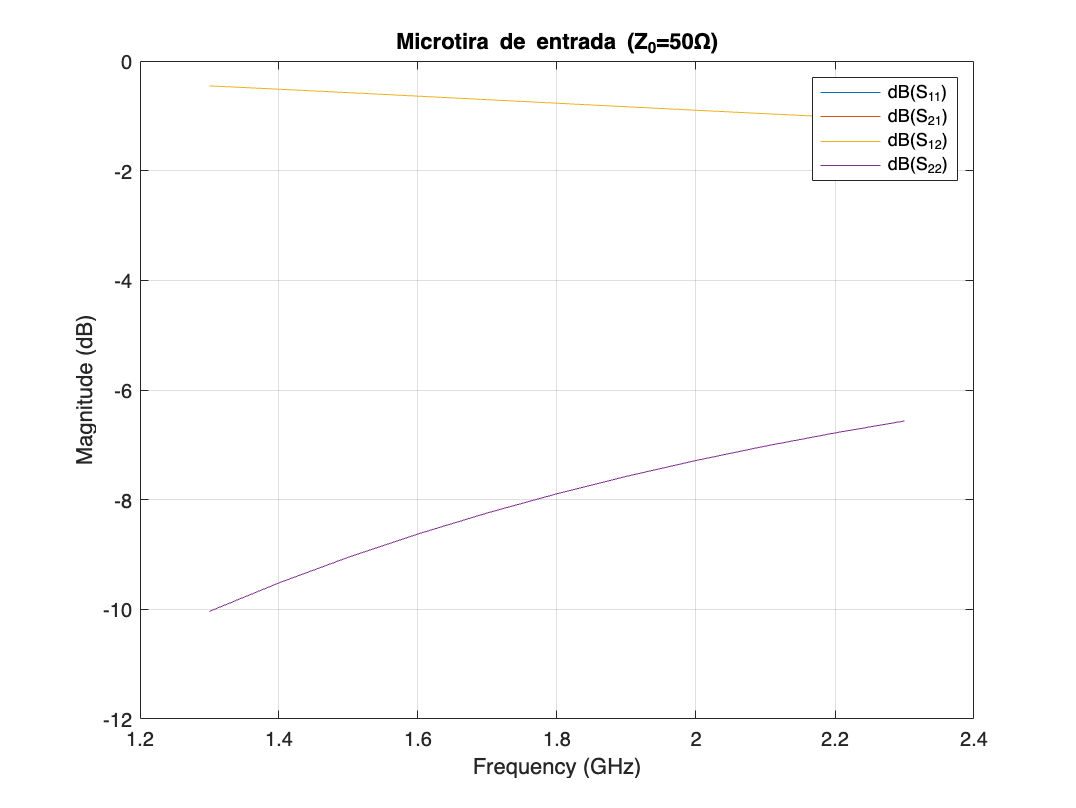

rfplot(s2)
title('Microtira de entrada (Z_0=50\Omega)')

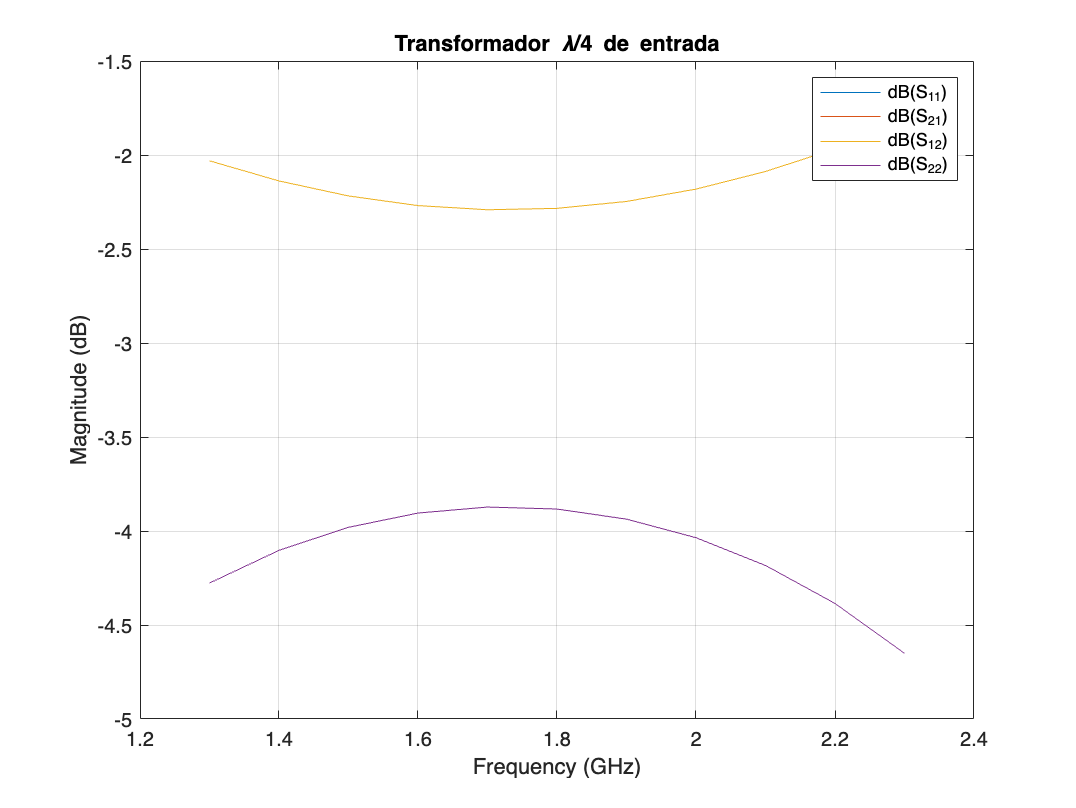

rfplot(s3)
title('Transformador \lambda/4 de entrada')

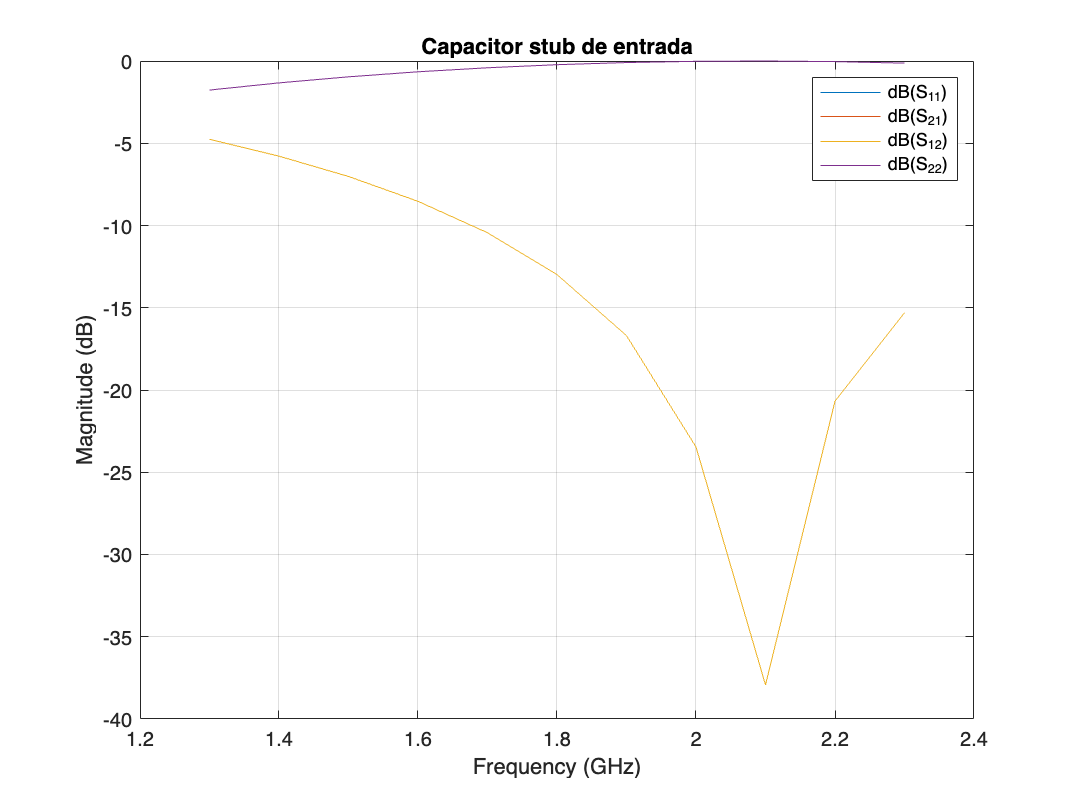

rfplot(s4)
title('Capacitor stub de entrada')

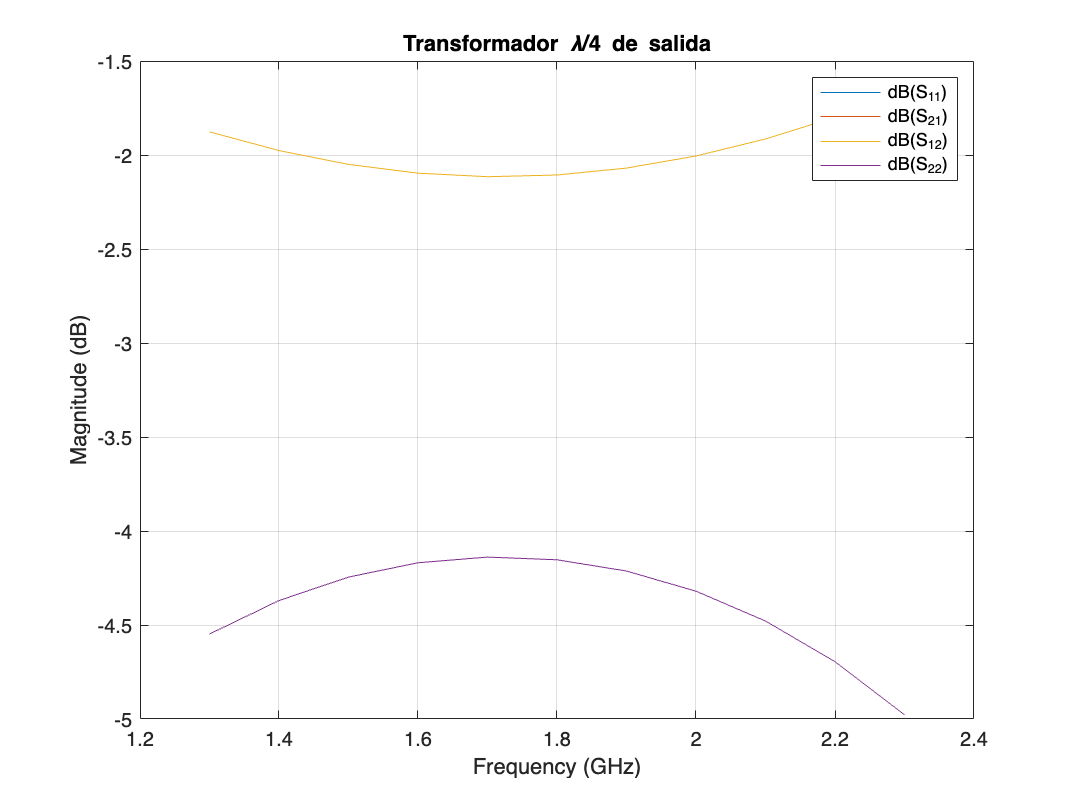

rfplot(s5)
title('Transformador \lambda/4 de salida')

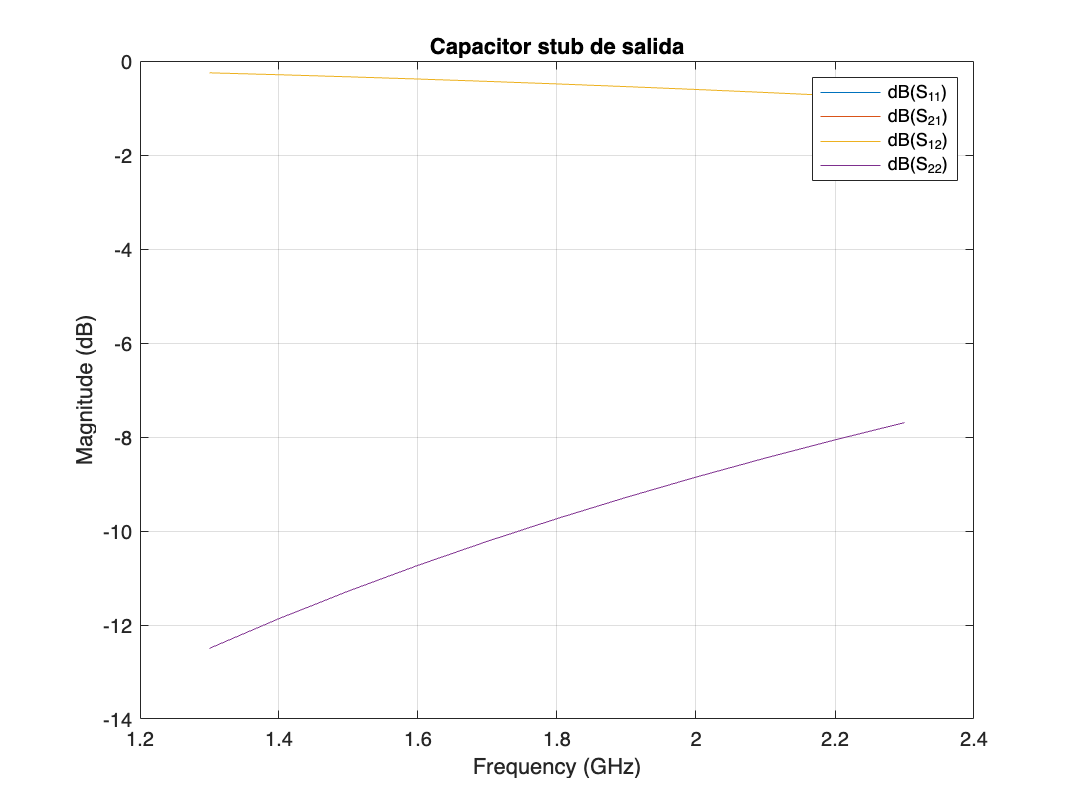

rfplot(s6)
title('Capacitor stub de salida')

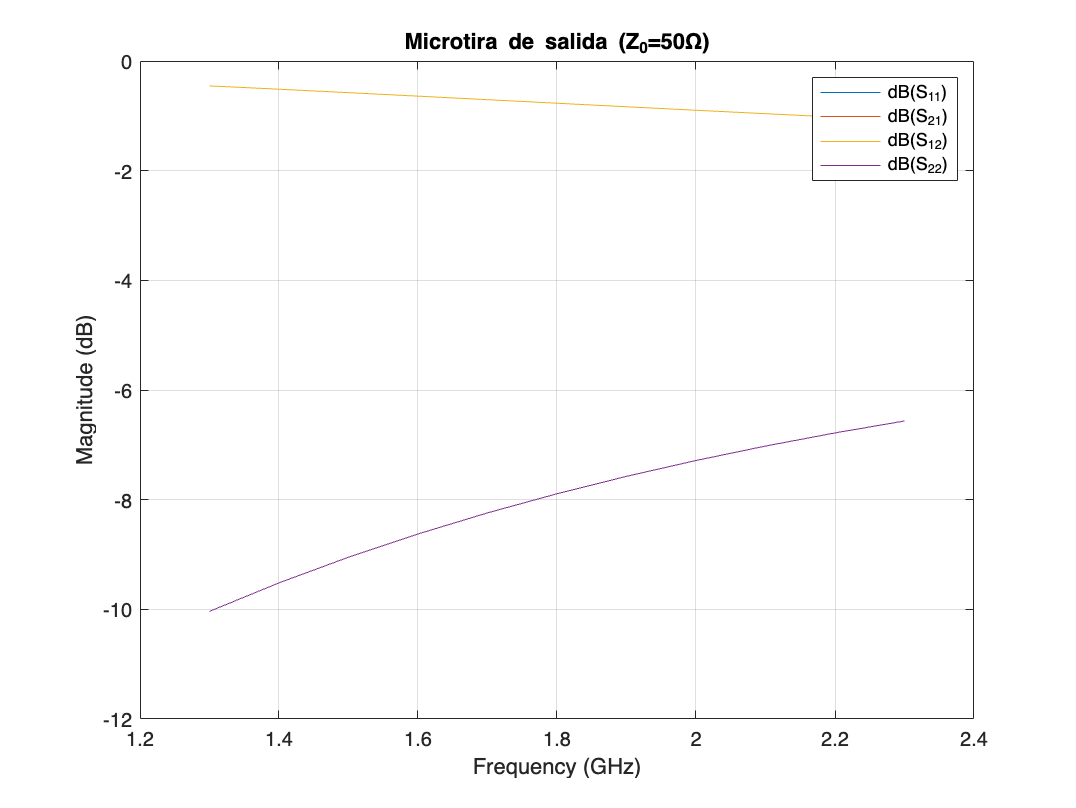

rfplot(s7)
title('Microtira de salida (Z_0=50\Omega)')

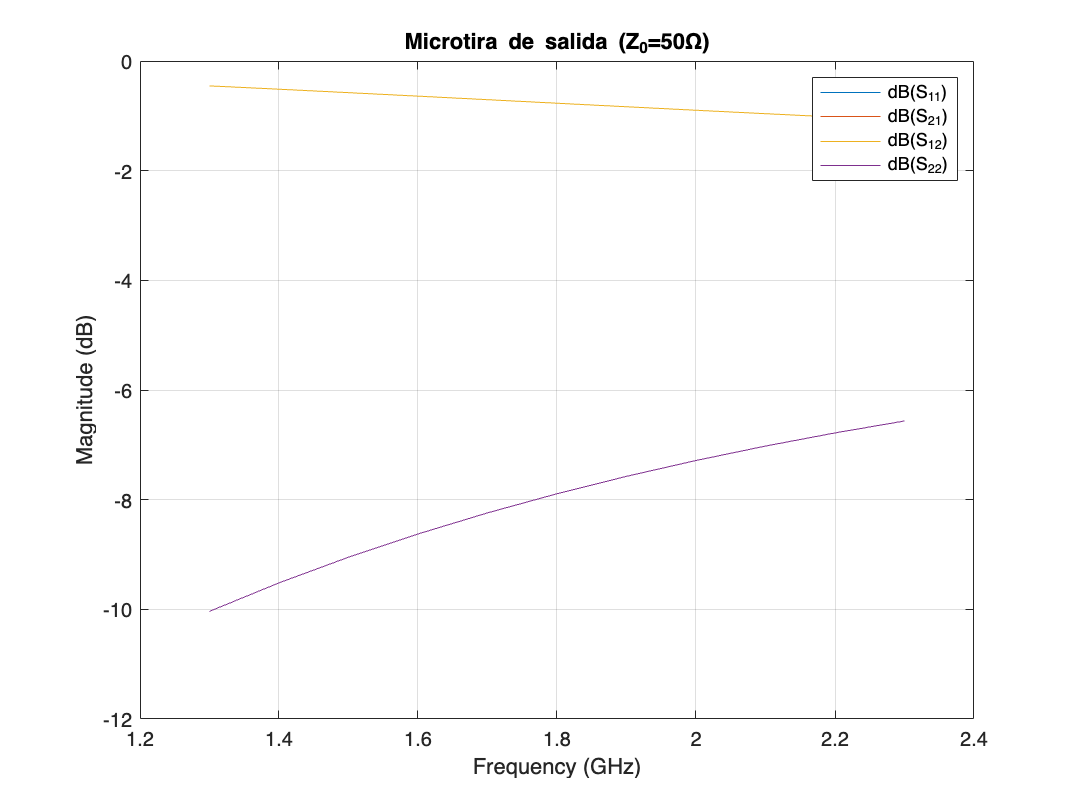

rfplot(s8)
title('Microtira de salida (Z_0=50\Omega)')

Se plotean los dos transformadores de $\frac{\lambda }{4}$ con sus respectivos capacitores sintetizados.

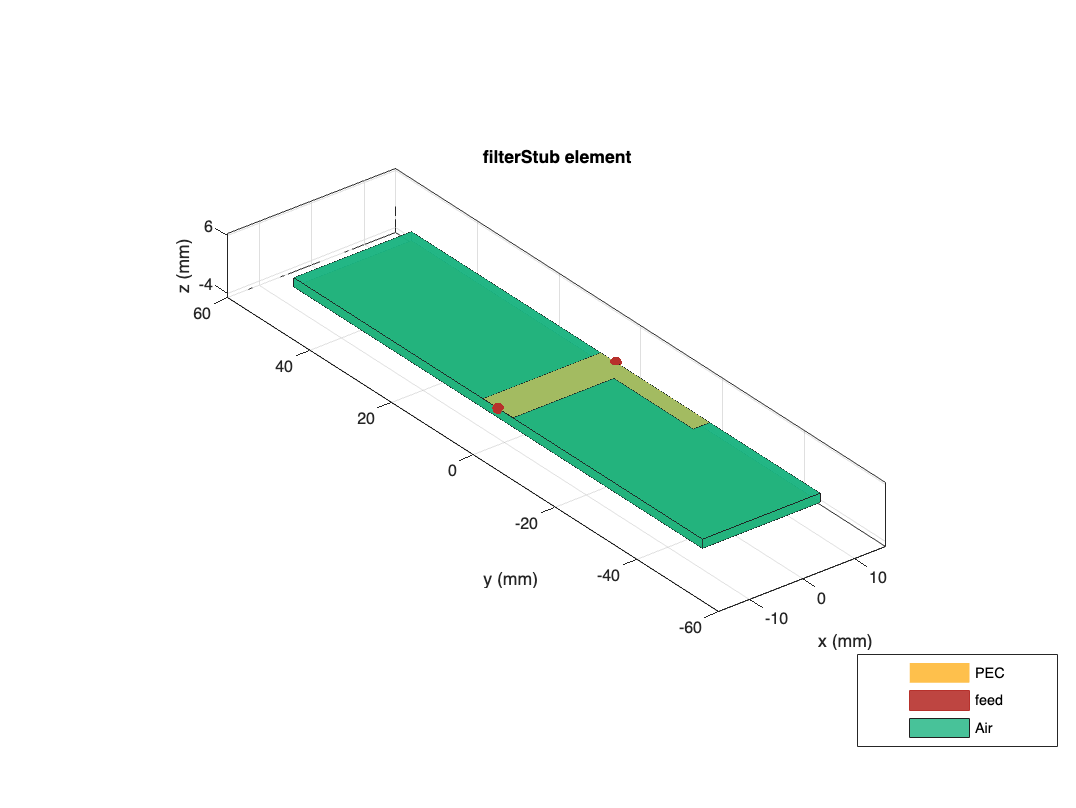

input_traf = filterStub;
input_traf.StubLength = 19.4e-3+3.645e-3;
input_traf.PortLineLength = 1e-20;
input_traf.PortLineWidth = 3.19e-3;
input_traf.StubWidth = 3.19e-3;
input_traf.SeriesLineLength = 22.5e-3;
input_traf.SeriesLineWidth = 7.29e-3;
input_traf.StubOffsetX = (11.24e-3)-(3.19e-3)/2;
input_traf.StubDirection = 0;
input_traf.StubShort = 0;
input_traf.GroundPlaneWidth = 100e-3;
d1 = dielectric('EpsilonR',4.15);
input_traf.Substrate = d1;
input_traf.Height = 1.6e-3;
figure,show(input_traf)

entrada = pcbcascade(tx1,input_traf);

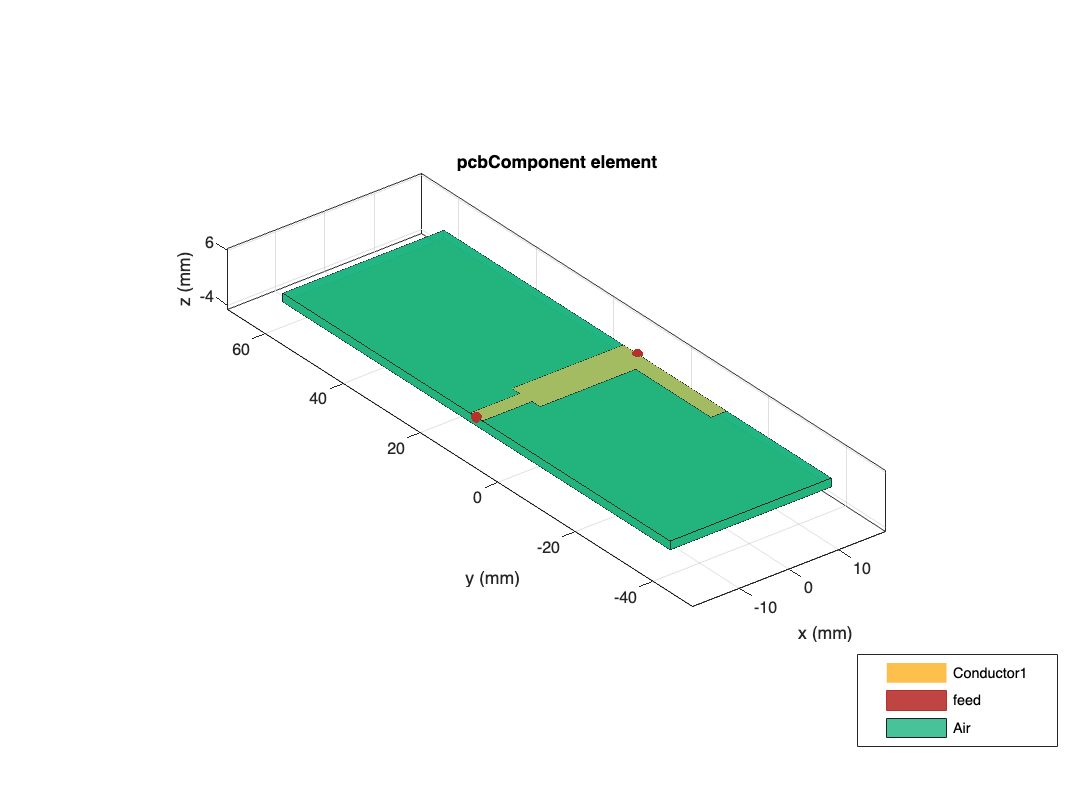

show(entrada)

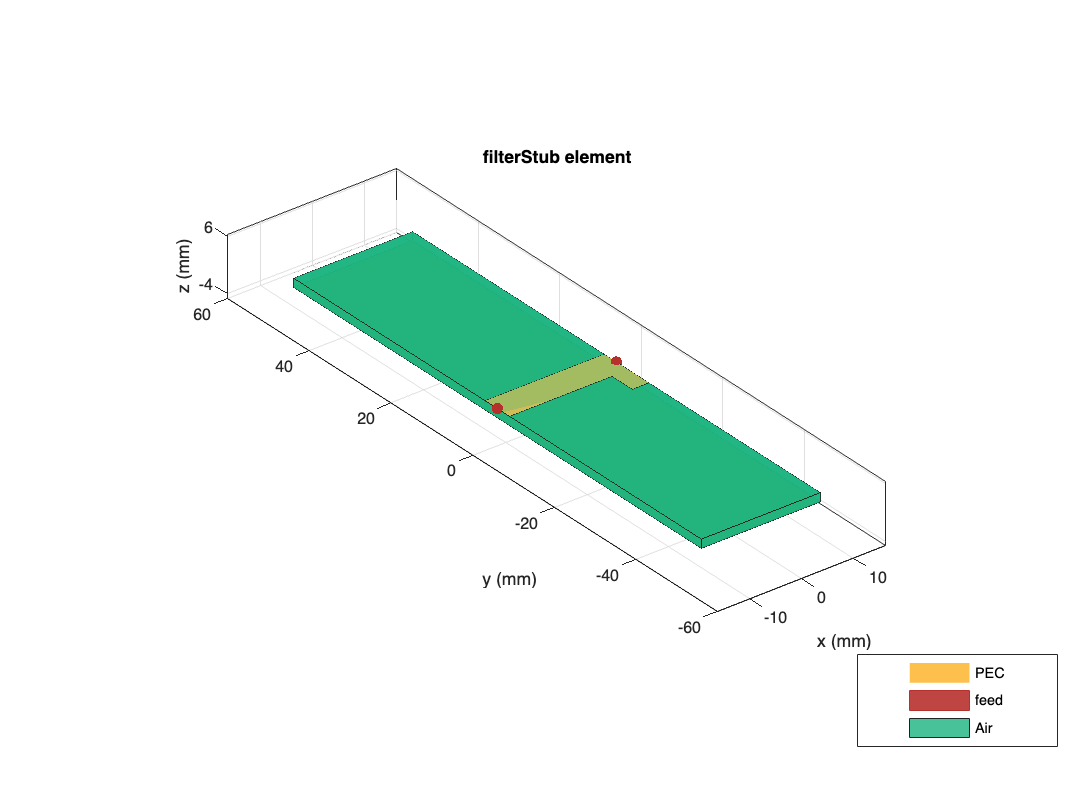

output_traf = filterStub;
output_traf.StubLength = 4.99e-3+2.995e-3;
output_traf.PortLineLength = 1e-20;
output_traf.PortLineWidth = 3.19e-3;
output_traf.StubWidth = 3.19e-3;
output_traf.SeriesLineLength = 22.79e-3;
output_traf.SeriesLineWidth = 5.99e-3;
output_traf.StubOffsetX = (11.394e-3)-(3.19e-3)/2;
output_traf.StubDirection = 0;
output_traf.StubShort = 0;
output_traf.GroundPlaneWidth = 100e-3;
output_traf.Substrate = d1;
output_traf.Height = 1.6e-3;
show(output_traf)

salida = pcbcascade(output_traf,tx1);

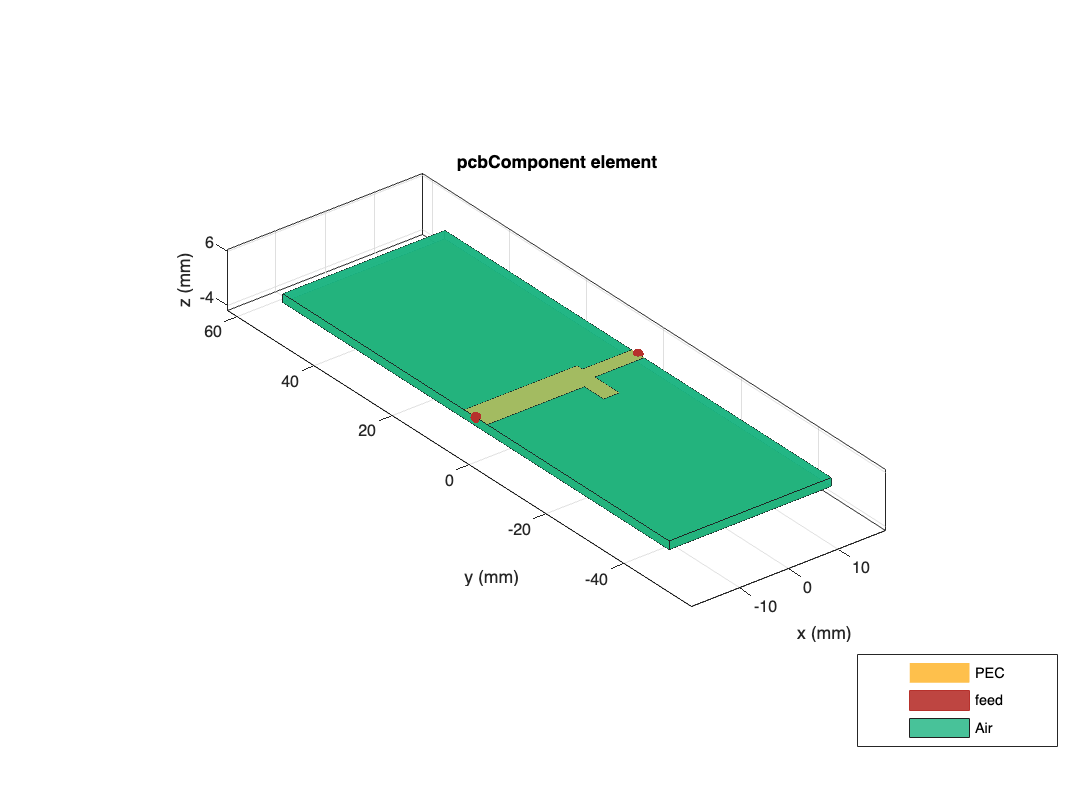

show(salida)